# Input:

ad = '/MATLAB Drive/0 GPS.txt';
% File path of the file
fprintf('Address: %s', ad)

Address: /MATLAB Drive/0 GPS.txt

fread(fopen('/MATLAB Drive/Sir.txt', ...
    'r'),'*char')'

ans = '47.641926692856515	47.641926692856'

## Pixel location

px = 257*ones(1,100);px(1:5)

ans =    257   257   257   257   257


py = [167 168 169 169 171 171 171 173 173 174
    176 176 177 177 177 178 179 180 181 182 
    182 183 184 184 185 186 186 187 188 188
    189 189 190 191 191 192 193 193 194 195
    195 196 197 197 198 199 199 200 201 202
    202 203 204 204 205 205 206 207 207 208
    209 209 210 211 211 212 213 213 214 215
    215 216 216 217 218 218 219 220 220 221
    222 222 223 223 224 225 225 226 227 227 
    228 229 229 230 231 231 232 232 234 234];
k = py'; ka = k(:)'; ka(1:5)

ans =    167   168   169   169   171


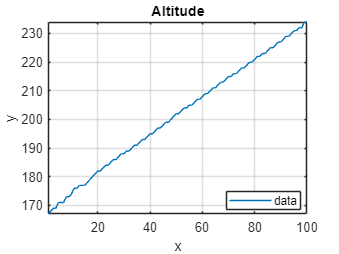

figure();
plot(k(:)'); % ,'b.'
axis tight % [0 1050 0 30]
xlabel('x')
ylabel('y')
% hold on;
% plot(ypred(cvgprMdl.Partition.test));
% hold off; % ,'predictions'
grid on
legend({'data'}, ...
    'Location','Best');
title('Altitude')

# Display:

format long
% format shortG

## Altitudes, Longitudes, L`atitude`:

c = fread(fopen(ad,'r'),'*char');
a = str2double(extractBetween(c', ...
    "t> {   'altitude': ",c(78:96)'));
l = str2double(extractBetween(c', ...
    c(78:96)',c(115:132)'));
lo = str2double(extractBetween(c', ...
    "'longitude': ",'}'));
fprintf('Some of text: %s\n', c(1:620)');

Some of text: Roof of the red car, target:	1.	<GeoPoint> {   'altitude': 123.79852294921875,
    'latitude': 47.6419266928565,
    'longitude': -122.14012507545267}

	2.	<ImuData> {   'angular_velocity': <Vector3r> {   'x_val': 0.0016028463141992688,
    'y_val': 0.00023396887991111726,
    'z_val': -0.001292117522098124},
    'linear_acceleration': <Vector3r> {   'x_val': 0.0469965822994709,
    'y_val': 0.008837218396365643,
    'z_val': -9.807531356811523},
    'orientation': <Quaternionr> {   'w_val': 0.9999998807907104,
    'x_val': 0.0,
    'y_val': 0.0,
    'z_val': 0.0},
    'time_stamp': 1697286239757648


fprintf('Input altitudes: ');

Input altitudes: 

fprintf('%f\t', a(1:7)')

123.798523	174.548035	174.816254	176.499268	177.906265	178.610031	180.365128	

fprintf('Input longitudes: ');

Input longitudes: 

fprintf('%f\t', lo(1:7)')

-122.140125	-122.140165	-122.140165	-122.140165	-122.140165	-122.140165	-122.140165	

fprintf('Input latitude: ');

Input latitude: 

fprintf('%f\t', l(1:7)')

47.641927	47.637493	47.637493	47.637493	47.637493	47.637493	47.637493	

% 47.6419266928565-la(1)
% 47.6419266928565-l(1)

ans =      0


# Altitude table:

la = 47.6419266928565*ones(101,1);la(1)

ans =   47.641926692856501


ya = a(1)*ones(101,1); ya(1)

ans =      1.237985229492188e+02


ta = table(a,lo,la,[512/2 px]',[288 ...
    /2 k(:)']',ya,'VariableNames',{ ...
    'Altitude', 'Longitude', 'Latitude', ...
    'PixelX', 'PixelY', 'Ycoordinate'});
fprintf('Drone data, output: Altitude');

Drone data, output: Altitude

ta(2:10,[1 3 end])

ans = 9x3 table
        Altitude            Latitude          Ycoordinate   
    ________________    ________________    ________________

    174.548034667969    47.6419266928565    123.798522949219
    174.816253662109    47.6419266928565    123.798522949219
    176.499267578125    47.6419266928565    123.798522949219
    177.906265258789    47.6419266928565    123.798522949219
     178.61003112793    47.6419266928565    123.798522949219
    180.365127563477    47.6419266928565    123.798522949219
    181.261978149414    47.6419266928565    123.798522949219
    182.802627563477    47.6419266928565    123.798522949219
    184.006759643555    47.6419266928565    123.798522949219


## tlt = ta(2:101,:)

idx = randperm(100)

idx =     99    32    40    22    34    92    91    35     6    55     3    96    68    16    69    11    54    30    45    77    60    74    78    72    62    70    51    33     7    86    38   100    58    76    81    89    42    28    17    41    47    98    80    14    46    56    63    93     8    67


% save("id.mat","idx") % ,"q"

% save("id.mat","py","px","tltsa"
% ,"tltra", ...
%     "tlts","tltr","tla","tlltr","-append")

load("id.mat")
whos("-file","id.mat")

  Name      Size             Bytes  Class     Attributes

  idx       1x100              800  double              



tltra = ta(1+sort(idx(21:100)),:);
tltra(2:10,[1 3 end])

ans = 9x3 table
        Altitude            Latitude          Ycoordinate   
    ________________    ________________    ________________

    174.816253662109    47.6419266928565    123.798522949219
    177.906265258789    47.6419266928565    123.798522949219
     178.61003112793    47.6419266928565    123.798522949219
    181.261978149414    47.6419266928565    123.798522949219
    182.802627563477    47.6419266928565    123.798522949219
    184.006759643555    47.6419266928565    123.798522949219
    185.700408935547    47.6419266928565    123.798522949219
    187.998580932617    47.6419266928565    123.798522949219
    189.441696166992    47.6419266928565    123.798522949219


tltsa = ta(1+sort(idx(1:20)),:);
tltsa(2:10,[1 3 end])

ans = 9x3 table
        Altitude            Latitude          Ycoordinate   
    ________________    ________________    ________________

    180.365127563477    47.6419266928565    123.798522949219
     186.87385559082    47.6419266928565    123.798522949219
    193.097885131836    47.6419266928565    123.798522949219
    200.921432495117    47.6419266928565    123.798522949219
    210.833923339844    47.6419266928565    123.798522949219
    213.666458129883    47.6419266928565    123.798522949219
    215.361129760742    47.6419266928565    123.798522949219
    216.633438110352    47.6419266928565    123.798522949219
    222.933303833008    47.6419266928565    123.798522949219


## Longitude table:

tl = table(a,lo,la, [512/2 px]',[288 ...
    /2 k(:)']',lo(1)*ones(101,1), ...
    'VariableNames',{'Altitude', ...
    'Longitude', 'Latitude', 'PixelX' ...
    ,'PixelY', 'Ylongitude'});
fprintf('Output: Longitude');tl(2:10,:)

Output: Longitude

ans = 9x6 table
        Altitude         Longitude         Latitude        PixelX    PixelY       Ylongitude    
    ________________    ___________    ________________    ______    ______    _________________

    174.548034667969    -122.140165    47.6419266928565     257       167      -122.140125075453
    174.816253662109    -122.140165    47.6419266928565     257       168      -122.140125075453
    176.499267578125    -122.140165    47.6419266928565     257       169      -122.140125075453
    177.906265258789    -122.140165    47.6419266928565     257       169      -122.140125075453
     178.61003112793    -122.140165    47.6419266928565     257       171      -122.140125075453
    180.365127563477    -122.140165    47.6419266928565     257       171      -122.140125075453
   

tlltr = tl(1+sort(idx(21:100)),:);
tlltr(2:10,[1 3 end])

ans = 9x3 table
        Altitude            Latitude           Ylongitude    
    ________________    ________________    _________________

    174.816253662109    47.6419266928565    -122.140125075453
    177.906265258789    47.6419266928565    -122.140125075453
     178.61003112793    47.6419266928565    -122.140125075453
    181.261978149414    47.6419266928565    -122.140125075453
    182.802627563477    47.6419266928565    -122.140125075453
    184.006759643555    47.6419266928565    -122.140125075453
    185.700408935547    47.6419266928565    -122.140125075453
    187.998580932617    47.6419266928565    -122.140125075453
    189.441696166992    47.6419266928565    -122.140125075453


tllts = tl(1+sort(idx(1:20)),:);
tllts(2:10,[1 3 end])

ans = 9x3 table
        Altitude            Latitude           Ylongitude    
    ________________    ________________    _________________

    180.365127563477    47.6419266928565    -122.140125075453
     186.87385559082    47.6419266928565    -122.140125075453
    193.097885131836    47.6419266928565    -122.140125075453
    200.921432495117    47.6419266928565    -122.140125075453
    210.833923339844    47.6419266928565    -122.140125075453
    213.666458129883    47.6419266928565    -122.140125075453
    215.361129760742    47.6419266928565    -122.140125075453
    216.633438110352    47.6419266928565    -122.140125075453
    222.933303833008    47.6419266928565    -122.140125075453


# Latitude table:

tla = table(a,lo,la ,[512/2 px]',[288 ...
    /2 k(:)']',l(1)*ones(101,1),['' ...
    'VariableNames'],{'Altitude', ...
    'Longitude', 'Latitude', 'PixelX', ...
    'PixelY', 'Ylatitude'});
fprintf('Drone data, output: Latitude');

Drone data, output: Latitude

tla(2:10,:)

ans = 9x6 table
        Altitude         Longitude         Latitude        PixelX    PixelY       Ylatitude    
    ________________    ___________    ________________    ______    ______    ________________

    174.548034667969    -122.140165    47.6419266928565     257       167      47.6419266928565
    174.816253662109    -122.140165    47.6419266928565     257       168      47.6419266928565
    176.499267578125    -122.140165    47.6419266928565     257       169      47.6419266928565
    177.906265258789    -122.140165    47.6419266928565     257       169      47.6419266928565
     178.61003112793    -122.140165    47.6419266928565     257       171      47.6419266928565
    180.365127563477    -122.140165    47.6419266928565     257       171      47.6419266928565
    181.261

tltr = tla(1+sort(idx(21:100)),:);
tltr(2:10,[1 3 end])

ans = 9x3 table
        Altitude            Latitude           Ylatitude    
    ________________    ________________    ________________

    174.816253662109    47.6419266928565    47.6419266928565
    177.906265258789    47.6419266928565    47.6419266928565
     178.61003112793    47.6419266928565    47.6419266928565
    181.261978149414    47.6419266928565    47.6419266928565
    182.802627563477    47.6419266928565    47.6419266928565
    184.006759643555    47.6419266928565    47.6419266928565
    185.700408935547    47.6419266928565    47.6419266928565
    187.998580932617    47.6419266928565    47.6419266928565
    189.441696166992    47.6419266928565    47.6419266928565


tlts = tla(1+sort(idx(1:20)),:);
tlts(2:10,[1 3 end])

ans = 9x3 table
        Altitude            Latitude           Ylatitude    
    ________________    ________________    ________________

    180.365127563477    47.6419266928565    47.6419266928565
     186.87385559082    47.6419266928565    47.6419266928565
    193.097885131836    47.6419266928565    47.6419266928565
    200.921432495117    47.6419266928565    47.6419266928565
    210.833923339844    47.6419266928565    47.6419266928565
    213.666458129883    47.6419266928565    47.6419266928565
    215.361129760742    47.6419266928565    47.6419266928565
    216.633438110352    47.6419266928565    47.6419266928565
    222.933303833008    47.6419266928565    47.6419266928565


# Longitude gpr:

% cross-validation:
% rng('default') % For reproducibility
gprMdlo = fitrgp(tlltr, ...
    'Ylongitude', ...
    'KernelFunction', ...
    'ardsquaredexponential',...
      'FitMethod','sr','PredictMethod', ...
      'fic','Standardize',1,'Sigma',.002)

gprMdlo =   RegressionGP
           PredictorNames: {'Altitude'  'Longitude'  'Latitude'  'PixelX'  'PixelY'}
             ResponseName: 'Ylongitude'
    CategoricalPredictors: []
        ResponseTransform: 'none'
          NumObservations: 80
           KernelFunction: 'ARDSquaredExponential'
        KernelInformation: [1x1 struct]
            BasisFunction: 'Constant'
                     Beta: -1.221401250754527e+02
                    Sigma: 0.001000000752046
        PredictorLocation: [5x1 double]
           PredictorScale: [5x1 double]
                    Alpha: [80x1 double]
         ActiveSetVectors: [80x5 double]
            PredictMethod: 'FIC'
            ActiveSetSize: 80
                FitMethod: 'SR'
          ActiveSetMethod: 'Random'
        IsActiveSetVector: [80x1 logical]
            LogLikelihood: 4.791055222412127e+02
         ActiveSetHistory: [1x1 struct]
           BCDInformation: []


  

% ...
    %   'Standardize',1, ...
    % 'Sigma',.002)
% fprintf('kfoldLoss = %e', kfoldLoss( ...
%     cvgprMdl))
% ypred = kfoldPredict(cvgprMdl);
% fprintf('kfoldPredict: ');
% fprintf('%f\t', ypred')

ypredlo = predict(gprMdlo,tllts(:, ...
    1:end-1).Variables);ypredl'

ans = 1.0e+02 *

  -1.221401250754527  -1.221401250754527  -1.221401250754527  -1.221401250754527  -1.221401250754527  -1.221401250754527  -1.221401250754527  -1.221401250754527  -1.221401250754527  -1.221401250754527  -1.221401250754527  -1.221401250754527  -1.221401250754527  -1.221401250754527  -1.221401250754527  -1.221401250754527  -1.221401250754527  -1.221401250754527  -1.221401250754527  -1.221401250754527


elo = (lo(1)-ypredlo(1))/lo(1) % 

elo =     -2.326975628430571e-16


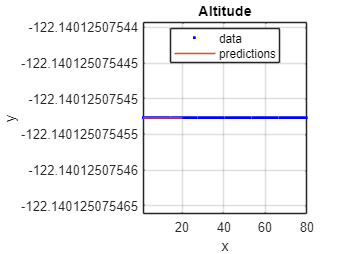

gprMdla =   RegressionGP
           PredictorNames: {'Altitude'  'Longitude'  'Latitude'  'PixelX'  'PixelY'}
             ResponseName: 'Ycoordinate'
    CategoricalPredictors: []
        ResponseTransform: 'none'
          NumObservations: 80
           KernelFunction: 'ARDSquaredExponential'
        KernelInformation: [1x1 struct]
            BasisFunction: 'Constant'
                     Beta: 1.237985229492188e+02
                    Sigma: 0.001000000830224
        PredictorLocation: [5x1 double]
           PredictorScale: [5x1 double]
                    Alpha: [80x1 double]
         ActiveSetVectors: [80x5 double]
            PredictMethod: 'FIC'
            ActiveSetSize: 80
                FitMethod: 'SR'
          ActiveSetMethod: 'Random'
        IsActiveSetVector: [80x1 logical]
            LogLikelihood: 4.791055157770294e+02
         ActiveSetHistory: [1x1 struct]
           BCDInformation: []


  

ans = 1.0e+02 *

   1.237985229492188   1.237985229492188   1.237985229492188   1.237985229492188   1.237985229492188   1.237985229492188   1.237985229492188   1.237985229492188   1.237985229492188   1.237985229492188   1.237985229492188   1.237985229492188   1.237985229492188   1.237985229492188   1.237985229492188   1.237985229492188   1.237985229492188   1.237985229492188   1.237985229492188   1.237985229492188


ea =     -2.842170943040401e-14


ans =      0


figure();
% y = table2array(ta(2:end,end));
plot(tlltr.Ylongitude,'b.'); 
% .Partition.tes
axis tight % [0 1050 0 30]
xlabel('x')
ylabel('y')
hold on;
plot(ypred1l);%ypred(cvgprMdl));
hold off;
grid on
legend({'data','predictions'}, ...
    'Location','Best');
title('Altitude')

# Laltitude gpr:

% cross-validation:
% rng('default') % For reproducibility
gprMdll = fitrgp(tltr, 'Ylatitude', ...
    'KernelFunction', ...
    'ardsquaredexponential',...
      'FitMethod','sr','PredictMethod', ...
      'fic','Standardize',1,'Sigma',.002)

gprMdll =   RegressionGP
           PredictorNames: {'Altitude'  'Longitude'  'Latitude'  'PixelX'  'PixelY'}
             ResponseName: 'Ylatitude'
    CategoricalPredictors: []
        ResponseTransform: 'none'
          NumObservations: 80
           KernelFunction: 'ARDSquaredExponential'
        KernelInformation: [1x1 struct]
            BasisFunction: 'Constant'
                     Beta: 47.641926692856501
                    Sigma: 0.001000000412871
        PredictorLocation: [5x1 double]
           PredictorScale: [5x1 double]
                    Alpha: [80x1 double]
         ActiveSetVectors: [80x5 double]
            PredictMethod: 'FIC'
            ActiveSetSize: 80
                FitMethod: 'SR'
          ActiveSetMethod: 'Random'
        IsActiveSetVector: [80x1 logical]
            LogLikelihood: 4.791053066133783e+02
         ActiveSetHistory: [1x1 struct]
           BCDInformation: []


  

% ...
    %   'Standardize',1, ...
    % 'Sigma',.002)
% fprintf('kfoldLoss = %e', kfoldLoss( ...
%     cvgprMdl))
% ypred = kfoldPredict(cvgprMdl);
% fprintf('kfoldPredict: ');
% fprintf('%f\t', ypred')

ypredl = predict(gprMdll,tlts(:,1:end- ...
    1).Variables);ypredl'

ans =   47.641926692856501  47.641926692856501  47.641926692856501  47.641926692856501  47.641926692856501  47.641926692856501  47.641926692856501  47.641926692856501  47.641926692856501  47.641926692856501  47.641926692856501  47.641926692856501  47.641926692856501  47.641926692856501  47.641926692856501  47.641926692856501  47.641926692856501  47.641926692856501  47.641926692856501  47.641926692856501


el = (l(1)-ypredl(1))/l(1)

el =      0
